Environment initialisation

addpath("matlab2tikz/src/");

Physical constants

G = 6.673e-11; % universal gravitational constant, m3 * kg-1 * s-2
M_E = 5.9722e24 ; % mass of the Earth, kg
R = 6371008.8; % radius of the Earth, m
Omega_E = 2*pi / 86400; % earth's rotation in rad / s

Omega_E_vector = [0;0;Omega_E]; % angular velocity vector for Earth's rotation in the ECI coordinate system

Effect of observation altitude to the range of a eavesdropping sensor in relation to different elevation angles of the terminal.

d = @(h,ele)(h ./ (tand(ele)) / 1000); % maximum range in kilometers

Let's plot d for elevation range of 10 deg to 90 deg and observation altitude in range of 100 meters to 20 km.

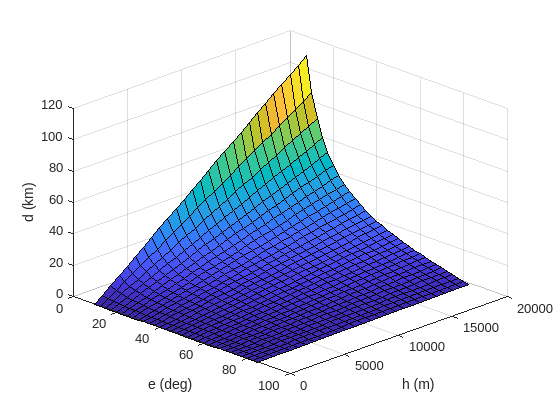

 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0.
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 


 *** You will need pgfplots version 1.12 or newer to compile the TikZ output.


ele = 10:2.5:85; % elevation angle in degrees
h = 0:750:20000; % aircraft altitude in meters

[H, E] = meshgrid(h, ele);

s = surf(E, H, d(H, E));
view(45,30);
ax = ancestor(s, 'axes');
ax.YAxis.Exponent = 0;
ax.ZAxis.Exponent = 0;
%ax.YLim = [0,20000];
%ax.XLim = [5,95];

xlabel('e (deg)');
ylabel('h (m)');
zlabel('d (km)');
matlab2tikz('doc/tikz_figures/fig-interception-range.tikz');

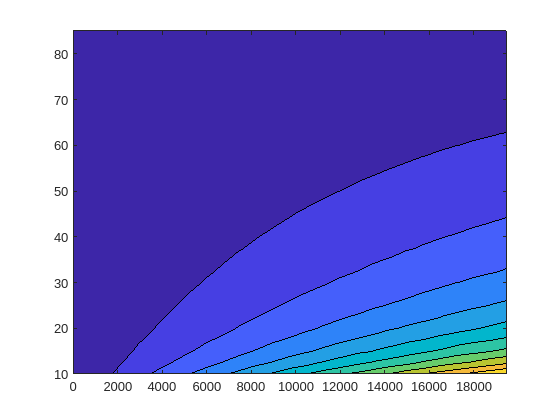

contourf(H,E,d(H,E));

Orbital radius in relation to velocity of the sub-satellite point (in km/s), ECI coordinate frame.

v_air = @(h,r_orbit)( (h+R) .* sqrt( (G*M_E) ./ (r_orbit + R).^3 ) );

Plot the velocity for orbital radius in range of 500 km to 37000 km.

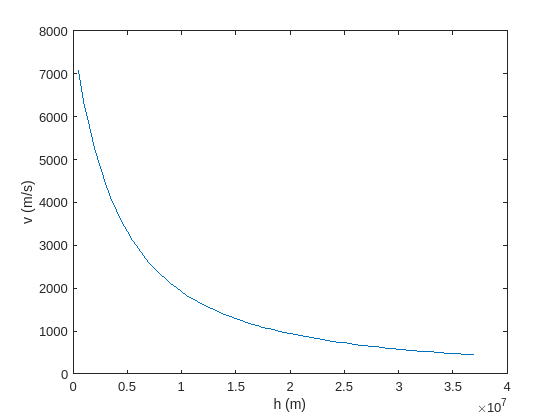

 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0.
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 


 *** You will need pgfplots version 1.3 or newer to compile the TikZ output.


r_orbit = 500e3:500e3:37e6;

[H_air, R_orbit] = meshgrid(h, r_orbit);

p_v_air = plot(r_orbit, v_air(10000,r_orbit));
xlabel('h (m)');
ylabel('v (m/s)');

matlab2tikz('doc/tikz_figures/fig-subsat-velocity-equatiorial.tikz');

In the case of GEO, Earth's rotation cancels the velocity of the sub-satellite point. Next, we will evaluate the effect of orbital period and inclination to the velocity of the sub-satellite point. We setup the orbits in the ECI coordinate system and account for the Earth's rotation by converting to ECF.

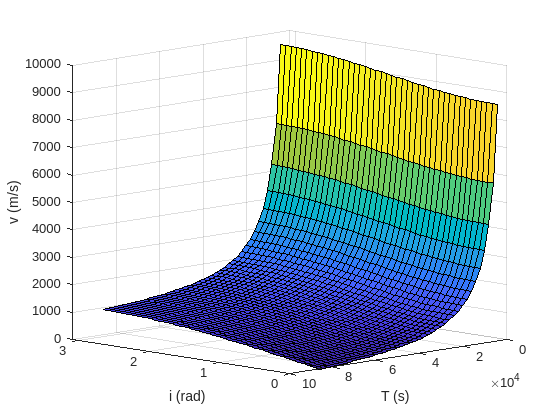

 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0.
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 


 *** You will need pgfplots version 1.12 or newer to compile the TikZ output.


inclination = 0:0.075:pi; % inclination in rad
orbital_period = 4400:2000:86400; % in seconds

roty = @(t)[cos(t) 0 sin(t); 0 1 0; -sin(t) 0 cos(t)] ;

omega_ECF_magnitude = @(i, T)( norm(roty(i) * ( (2*pi / T) .* [0;0;1] ) - Omega_E_vector));

[I_orbit, T_orbit] = meshgrid(inclination, orbital_period);

omega_arr = arrayfun(omega_ECF_magnitude, I_orbit, T_orbit);

v_air_arr = R .* omega_arr;

s_omega_ECF_norm = surf(I_orbit, T_orbit, v_air_arr);

xlabel('i (rad)'); % inclination
ylabel('T (s)'); % orbital period
zlabel('v (m/s)'); % sub-satellite velocity 
view(-135,10);

matlab2tikz('doc/tikz_figures/fig-subsat-velocity-inclined.tikz');

Listening window at a set beamwidth.

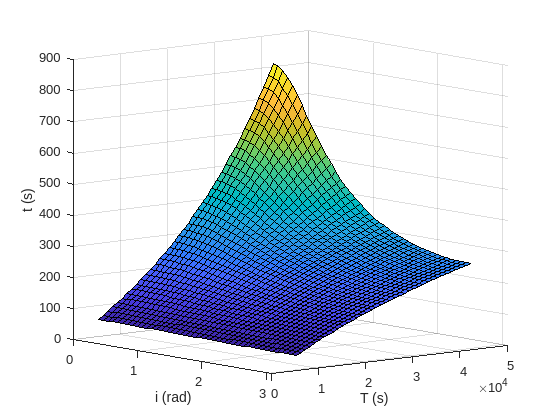

 *** (To disable info messages, pass ['showInfo', false] to matlab2tikz.)
 *** (For all other options, type 'help matlab2tikz'.)
 *** 
 *** 
 *** This is matlab2tikz v1.1.0.
 *** 
 *** The latest developments can be retrieved from <a href="https://github.com/matlab2tikz/matlab2tikz/tree/develop">our development branch</a>.
 *** You can find more documentation on <a href="https://github.com/matlab2tikz/matlab2tikz">our GitHub page</a> and <a href="https://github.com/matlab2tikz/matlab2tikz/wiki">wiki</a>.
 *** If you encounter bugs or want a new feature, go to <a href="https://github.com/matlab2tikz/matlab2tikz/issues">our issue tracker</a>.
 *** Please visit <a href="http://www.mathworks.com/matlabcentral/fileexchange/22022-matlab2tikz-matlab2tikz">FileExchange</a> to rate matlab2tikz or download the stable release.
 *** 


 *** You will need pgfplots version 1.12 or newer to compile the TikZ output.


orbital_period = 5400:1000:42400; % in seconds 

beamwidth = deg2rad(3.5); % beamwidth in rad

roty = @(t)[cos(t) 0 sin(t); 0 1 0; -sin(t) 0 cos(t)] ;

[I_orbit, T_orbit] = meshgrid(inclination, orbital_period);

omega_arr = arrayfun(omega_ECF_magnitude, I_orbit, T_orbit);

t_pass = beamwidth ./ omega_arr; % listening window, fixed aircraft

s_omega_ECF_norm = surf(I_orbit, T_orbit, t_pass);

xlabel('i (rad)'); % inclination
ylabel('T (s)'); % orbital period
zlabel('t (s)'); % maximum listening window / satellite pass
view([-310 9]);

matlab2tikz('doc/tikz_figures/fig-listening-window.tikz');

OneWeb visualisation

startTime=datetime("18-Oct-2023 9:00:00");
endTime=datetime("18-Oct-2023 9:02:25");
sampleTime=60;

sc = satelliteScenario(startTime, endTime, sampleTime);

% 1200 km Earth orbit, 86.4 deg inclination, 588 sats in 12 planes. Phasing?
%ow = walkerStar(sc, 1200e3+6378.14e3, 86.4, 588, 12, 1, Name="OneWeb");

utKajaani = groundStation(sc, 64.2, 27.7, Name="Kajaani");
serverEspoo = groundStation(sc, 60.2, 24.8, Name="Espoo");
serverWormerveer = groundStation(sc, 52.5, 4.8, Name="Wormerveer");
popLondon = groundStation(sc, 51.5, -0.2, Name="London");

set(utKajaani, ShowLabel=false);
set(utKajaani, MarkerColor="Red");
set(serverEspoo, ShowLabel=false);
set(serverEspoo, MarkerColor="Green");
set(serverWormerveer, ShowLabel=false);
set(serverWormerveer, MarkerColor="Green");
set(popLondon, ShowLabel=false);
set(popLondon, MarkerColor="Yellow");

ow = satellite(sc, "src/oneweb.tle", Name="OW");

set(ow(1:634), ShowLabel=false);
set(ow(1:634), MarkerSize=3);
set(ow(1:634).Orbit, LineWidth=1);

viewer3D = satelliteScenarioViewer(sc, Basemap="bluegreen");

campos(viewer3D, 40, 18);